# Quadruped robot MBRL training tasks

Test for model based RL in MATLAB

Retrived from: [https://www.mathworks.com/help/reinforcement-learning/ug/model-based-reinforcement-learning-using-custom-training-loop.html](https://www.mathworks.com/help/reinforcement-learning/ug/model-based-reinforcement-learning-using-custom-training-loop.html)

## Create Environment

clear
clc
seedNum = 36;
rng(seedNum)
% load("modelParams.mat")
vali = 1;
if vali == 0
    mdl = 'RLtrot';
    isUsePretrainedAgent = 0;
    isUseExtAct = 0;
    SaveAgentReward = 150;
    StopTrainReward = 250;
    DiscountFactor = 0.96;
    criticLearnRate = 2e-3; %2
    actorLearnRate = 1e-3; %1 
elseif vali == 1
    isUsePretrainedAgent = 1;
    isUseExtAct = 1;
    mdl = 'RLvali_2021b';
    SaveAgentReward = 100;
    StopTrainReward = 120;
    DiscountFactor = 0.98;
    criticLearnRate = 1e-3; %2
    actorLearnRate = 5e-4; %1
else
    isUsePretrainedAgent = 0;
    mdl = 'RLvali_2021b';
    SaveAgentReward = 100;
    StopTrainReward = 120;
    DiscountFactor = 0.98;
    criticLearnRate = 1e-3; %2
    actorLearnRate = 5e-4; %1
%     isResume = 1;
%     preTrainingStats = ;
end
% robot animation on/off
set_param(mdl,'SimMechanicsOpenEditorOnUpdate','on','FastRestart','on') 

numAct = 4;
% Obs include: #rot x,y,z #v x,y,z #fn: FR,FL,RL,RR
numObs = 10 + numAct;

% Normalization
load("norm_para_all.mat")
state_init = [0	0 0	0 0 0 0.5 0.5 0.5 0.5];
x_norm_init=(state_init - y_norm_min)./y_norm_range;

% Robot settings
alpha_r_gain = 0;
alpha_b_gain = pi/5;
z_l_gain = 8e-3;

% Robot runtime
Tf = 5;
Ts = 0.05;

% added in amplitude 1
rotVariance = 0.002; % 0.001
fnVariance = 0.005; % 0.002
speedVariance = 0.002; % 0.001

## Training settings

#### Target speed

VRef = 0.5; % reference velocity

#### Actor-Critic learning settings

TargetSmoothFactor = 1e-3;

ExperienceBufferLength = 16384; % 2^14
MiniBatchSize = 4096; %2^12

EntropyWeight = 1;
EntropyLearnRate = 1e-4;
TargetEntropy = -numAct*1;

maxEpisodes = 400;

maxSteps = floor(Tf/Ts);

% !!! For continued/curriculum training -->
% !!!Change dir to run1,2,3 to avoid overlapping saved agents
SaveAgentDir = pwd+"\savedAgents";

if ~exist(SaveAgentDir, 'dir')
    mkdir(SaveAgentDir)
end

UseParallel = false;
numsWorkers = 3;

#### Overall training settings

doTraining = 1; % if not train, noise is disabled

startAgentTime = 32*Ts;
isCheckDone = 1;
isContactBoolean = 1;

% !!! for continued training -->
% !!! Change the value to 1 and update the latest agent!
if isUsePretrainedAgent == 0
    fprintf('Training ready');
else
    pretrainedAgent = SaveAgentDir + "\Agent233.mat";
end
% !!! for curriculum training -->
% !!! for now (1224), use agent : 
%  "savedAgents\Agent035ForCurriculum\agent035.mat"

## Create environment info

actInfo = rlNumericSpec([numAct 1],'LowerLimit',0,'UpperLimit', 1);
actInfo.Name = 'actions';

obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

blk = [mdl, '/RL Agent'];
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo,'UseFastRestart','on');


Create storage for entropy record and episode number

% EpiCount = 0;
% instantTrainingStats = [];
entropyListSize = maxSteps*maxEpisodes;
EntropyList = zeros(entropyListSize, 1);
EntropyList(1)=TargetEntropy;

EntropyWeightList = zeros(entropyListSize, 1);
EntropyWeightList(1)=EntropyWeight;

## Specify agent training options (parallel training try)

maxSteps = floor(Tf/Ts);  

trainOpts = rlTrainingOptions(...
    'UseParallel',UseParallel,...
    'MaxEpisodes',maxEpisodes,...
    'MaxStepsPerEpisode',maxSteps,...
    'ScoreAveragingWindowLength',10,...
    'Verbose',true,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',StopTrainReward,...                   
    'SaveAgentCriteria','EpisodeReward',... 
    'SaveAgentValue',SaveAgentReward,...
    'SaveAgentDirectory', SaveAgentDir);

if trainOpts.UseParallel == true
    delete(gcp('nocreate'));
    parpool(numsWorkers); % specify the number of workers
    %set_param(mdl,'SimMechanicsOpenEditorOnUpdate','off')
    trainOpts.ParallelizationOptions.Mode = 'async';
    trainOpts.ParallelizationOptions.StepsUntilDataIsSent = -1;
    trainOpts.ParallelizationOptions.DataToSendFromWorkers = 'Experiences';
end

## Critic Construction

if isUsePretrainedAgent
    load(pretrainedAgent)
    if exist('saved_agent','var')
        agent = saved_agent;
    end
else
    createAgent
end

## Train or test agent

Episode:   1/400 | Episode reward:  -250.01 | Episode steps:  100 | Average reward:  -250.01 | Step Count:  100 | Episode Q0:    -3.01


Episode:   2/400 | Episode reward:    -1.68 | Episode steps:   50 | Average reward:  -125.84 | Step Count:  150 | Episode Q0:    -3.16


Episode:   3/400 | Episode reward:   -52.61 | Episode steps:  100 | Average reward:  -101.43 | Step Count:  250 | Episode Q0:    -3.10


Episode:   4/400 | Episode reward:   -76.72 | Episode steps:  100 | Average reward:   -95.26 | Step Count:  350 | Episode Q0:    -2.93


Episode:   5/400 | Episode reward:   -48.13 | Episode steps:  100 | Average reward:   -85.83 | Step Count:  450 | Episode Q0:    -3.57


Episode:   6/400 | Episode reward:   -71.46 | Episode steps:  100 | Average reward:   -83.44 | Step Count:  550 | Episode Q0:    -3.78


Episode:   7/400 | Episode reward:   -45.75 | Episode steps:  100 | Average reward:   -78.05 | Step Count:  650 | Episode Q0:    -3.37


Episode:   8/400 | Episode reward:   -34.71 | Episode steps:  100 | Average reward:   -72.63 | Step Count:  750 | Episode Q0:    -3.58


Episode:   9/400 | Episode reward:   -29.32 | Episode steps:  100 | Average reward:   -67.82 | Step Count:  850 | Episode Q0:    -3.19


Episode:  10/400 | Episode reward:   -35.16 | Episode steps:  100 | Average reward:   -64.56 | Step Count:  950 | Episode Q0:    -2.85


Episode:  11/400 | Episode reward:   -26.82 | Episode steps:  100 | Average reward:   -42.24 | Step Count: 1050 | Episode Q0:    -3.44


Episode:  12/400 | Episode reward:   -14.81 | Episode steps:  100 | Average reward:   -43.55 | Step Count: 1150 | Episode Q0:    -2.74


Episode:  13/400 | Episode reward:    -2.81 | Episode steps:  100 | Average reward:   -38.57 | Step Count: 1250 | Episode Q0:    -3.18


Episode:  14/400 | Episode reward:    -1.06 | Episode steps:  100 | Average reward:   -31.00 | Step Count: 1350 | Episode Q0:    -2.86


Episode:  15/400 | Episode reward:     0.88 | Episode steps:  100 | Average reward:   -26.10 | Step Count: 1450 | Episode Q0:    -2.77


Episode:  16/400 | Episode reward:   -12.49 | Episode steps:  100 | Average reward:   -20.21 | Step Count: 1550 | Episode Q0:    -2.62


Episode:  17/400 | Episode reward:     3.55 | Episode steps:  100 | Average reward:   -15.28 | Step Count: 1650 | Episode Q0:    -2.56


Episode:  18/400 | Episode reward:     4.05 | Episode steps:  100 | Average reward:   -11.40 | Step Count: 1750 | Episode Q0:    -2.67


Episode:  19/400 | Episode reward:   -13.87 | Episode steps:  100 | Average reward:    -9.85 | Step Count: 1850 | Episode Q0:    -2.61


Episode:  20/400 | Episode reward:    12.46 | Episode steps:  100 | Average reward:    -5.09 | Step Count: 1950 | Episode Q0:    -2.38


Episode:  21/400 | Episode reward:   -36.49 | Episode steps:  100 | Average reward:    -6.06 | Step Count: 2050 | Episode Q0:    -3.05


Episode:  22/400 | Episode reward:     2.67 | Episode steps:  100 | Average reward:    -4.31 | Step Count: 2150 | Episode Q0:    -2.96


Episode:  23/400 | Episode reward:     3.08 | Episode steps:  100 | Average reward:    -3.72 | Step Count: 2250 | Episode Q0:    -2.98


Episode:  24/400 | Episode reward:     3.08 | Episode steps:  100 | Average reward:    -3.31 | Step Count: 2350 | Episode Q0:    -3.01


Episode:  25/400 | Episode reward:     3.91 | Episode steps:  100 | Average reward:    -3.01 | Step Count: 2450 | Episode Q0:    -2.90


Episode:  26/400 | Episode reward:     1.64 | Episode steps:  100 | Average reward:    -1.59 | Step Count: 2550 | Episode Q0:    -2.82


Episode:  27/400 | Episode reward:    -0.87 | Episode steps:  100 | Average reward:    -2.03 | Step Count: 2650 | Episode Q0:    -3.08


Episode:  28/400 | Episode reward:     2.33 | Episode steps:  100 | Average reward:    -2.21 | Step Count: 2750 | Episode Q0:    -3.14


Episode:  29/400 | Episode reward:     3.17 | Episode steps:  100 | Average reward:    -0.50 | Step Count: 2850 | Episode Q0:    -3.16


Episode:  30/400 | Episode reward:    -0.06 | Episode steps:  100 | Average reward:    -1.76 | Step Count: 2950 | Episode Q0:    -3.12


Episode:  31/400 | Episode reward:     0.56 | Episode steps:  100 | Average reward:     1.95 | Step Count: 3050 | Episode Q0:    -3.29


Episode:  32/400 | Episode reward:     1.41 | Episode steps:  100 | Average reward:     1.82 | Step Count: 3150 | Episode Q0:    -3.03


Episode:  33/400 | Episode reward:    -1.43 | Episode steps:  100 | Average reward:     1.37 | Step Count: 3250 | Episode Q0:    -3.13


Episode:  34/400 | Episode reward:     4.88 | Episode steps:  100 | Average reward:     1.55 | Step Count: 3350 | Episode Q0:    -3.33


Episode:  35/400 | Episode reward:    -1.55 | Episode steps:  100 | Average reward:     1.01 | Step Count: 3450 | Episode Q0:    -3.00


Episode:  36/400 | Episode reward:     0.21 | Episode steps:  100 | Average reward:     0.86 | Step Count: 3550 | Episode Q0:    -3.27


Episode:  37/400 | Episode reward:    -0.04 | Episode steps:  100 | Average reward:     0.95 | Step Count: 3650 | Episode Q0:    -3.54


Episode:  38/400 | Episode reward:     1.47 | Episode steps:  100 | Average reward:     0.86 | Step Count: 3750 | Episode Q0:    -3.32


Episode:  39/400 | Episode reward:     2.33 | Episode steps:  100 | Average reward:     0.78 | Step Count: 3850 | Episode Q0:    -3.20


Episode:  40/400 | Episode reward:     1.11 | Episode steps:  100 | Average reward:     0.90 | Step Count: 3950 | Episode Q0:    -3.18


Episode:  41/400 | Episode reward:     1.84 | Episode steps:  100 | Average reward:     1.02 | Step Count: 4050 | Episode Q0:    -3.11


Episode:  42/400 | Episode reward:    -0.17 | Episode steps:  100 | Average reward:     0.87 | Step Count: 4150 | Episode Q0:    -3.25


Episode:  43/400 | Episode reward:     1.82 | Episode steps:  100 | Average reward:     1.19 | Step Count: 4250 | Episode Q0:    -3.20


Episode:  44/400 | Episode reward:     3.21 | Episode steps:  100 | Average reward:     1.02 | Step Count: 4350 | Episode Q0:    -3.16


Episode:  45/400 | Episode reward:     0.62 | Episode steps:  100 | Average reward:     1.24 | Step Count: 4450 | Episode Q0:    -3.23


Episode:  46/400 | Episode reward:     1.50 | Episode steps:  100 | Average reward:     1.37 | Step Count: 4550 | Episode Q0:    -3.43


Episode:  47/400 | Episode reward:     2.05 | Episode steps:  100 | Average reward:     1.58 | Step Count: 4650 | Episode Q0:    -3.23


Episode:  48/400 | Episode reward:     2.55 | Episode steps:  100 | Average reward:     1.68 | Step Count: 4750 | Episode Q0:    -3.19


Episode:  49/400 | Episode reward:     2.52 | Episode steps:  100 | Average reward:     1.70 | Step Count: 4850 | Episode Q0:    -3.13


Episode:  50/400 | Episode reward:     4.14 | Episode steps:  100 | Average reward:     2.01 | Step Count: 4950 | Episode Q0:    -3.17


Episode:  51/400 | Episode reward:     3.56 | Episode steps:  100 | Average reward:     2.18 | Step Count: 5050 | Episode Q0:    -3.27


Episode:  52/400 | Episode reward:     4.13 | Episode steps:  100 | Average reward:     2.61 | Step Count: 5150 | Episode Q0:    -3.23


Episode:  53/400 | Episode reward:     2.94 | Episode steps:  100 | Average reward:     2.72 | Step Count: 5250 | Episode Q0:    -3.17


Episode:  54/400 | Episode reward:     1.99 | Episode steps:  100 | Average reward:     2.60 | Step Count: 5350 | Episode Q0:    -2.93


Episode:  55/400 | Episode reward:     3.06 | Episode steps:  100 | Average reward:     2.84 | Step Count: 5450 | Episode Q0:    -3.04


Episode:  56/400 | Episode reward:     5.29 | Episode steps:  100 | Average reward:     3.22 | Step Count: 5550 | Episode Q0:    -3.13


Episode:  57/400 | Episode reward:     3.76 | Episode steps:  100 | Average reward:     3.39 | Step Count: 5650 | Episode Q0:    -3.29


Episode:  58/400 | Episode reward:     7.38 | Episode steps:  100 | Average reward:     3.88 | Step Count: 5750 | Episode Q0:    -2.98


Episode:  59/400 | Episode reward:     8.76 | Episode steps:  100 | Average reward:     4.50 | Step Count: 5850 | Episode Q0:    -3.05


Episode:  60/400 | Episode reward:     8.06 | Episode steps:  100 | Average reward:     4.89 | Step Count: 5950 | Episode Q0:    -3.40


Episode:  61/400 | Episode reward:     6.34 | Episode steps:  100 | Average reward:     5.17 | Step Count: 6050 | Episode Q0:    -3.14


Episode:  62/400 | Episode reward:     9.13 | Episode steps:  100 | Average reward:     5.67 | Step Count: 6150 | Episode Q0:    -3.19


Episode:  63/400 | Episode reward:     2.05 | Episode steps:  100 | Average reward:     5.58 | Step Count: 6250 | Episode Q0:    -3.10


Episode:  64/400 | Episode reward:     7.21 | Episode steps:  100 | Average reward:     6.10 | Step Count: 6350 | Episode Q0:    -3.18


Episode:  65/400 | Episode reward:    10.82 | Episode steps:  100 | Average reward:     6.88 | Step Count: 6450 | Episode Q0:    -3.22


Episode:  66/400 | Episode reward:     9.26 | Episode steps:  100 | Average reward:     7.28 | Step Count: 6550 | Episode Q0:    -3.23


Episode:  67/400 | Episode reward:    14.05 | Episode steps:  100 | Average reward:     8.31 | Step Count: 6650 | Episode Q0:    -3.13


Episode:  68/400 | Episode reward:    12.66 | Episode steps:  100 | Average reward:     8.83 | Step Count: 6750 | Episode Q0:    -3.18


Episode:  69/400 | Episode reward:    14.49 | Episode steps:  100 | Average reward:     9.41 | Step Count: 6850 | Episode Q0:    -3.27


Episode:  70/400 | Episode reward:    16.59 | Episode steps:  100 | Average reward:    10.26 | Step Count: 6950 | Episode Q0:    -3.31


Episode:  71/400 | Episode reward:    12.81 | Episode steps:  100 | Average reward:    10.91 | Step Count: 7050 | Episode Q0:    -3.24


Episode:  72/400 | Episode reward:    10.13 | Episode steps:  100 | Average reward:    11.01 | Step Count: 7150 | Episode Q0:    -2.84


Episode:  73/400 | Episode reward:     7.65 | Episode steps:  100 | Average reward:    11.57 | Step Count: 7250 | Episode Q0:    -2.98


Episode:  74/400 | Episode reward:     9.59 | Episode steps:  100 | Average reward:    11.80 | Step Count: 7350 | Episode Q0:    -2.97


Episode:  75/400 | Episode reward:    14.64 | Episode steps:  100 | Average reward:    12.19 | Step Count: 7450 | Episode Q0:    -3.05


Episode:  76/400 | Episode reward:    12.29 | Episode steps:  100 | Average reward:    12.49 | Step Count: 7550 | Episode Q0:    -2.91


Episode:  77/400 | Episode reward:     7.50 | Episode steps:  100 | Average reward:    11.83 | Step Count: 7650 | Episode Q0:    -3.17


Episode:  78/400 | Episode reward:     6.98 | Episode steps:  100 | Average reward:    11.27 | Step Count: 7750 | Episode Q0:    -3.05


Episode:  79/400 | Episode reward:    18.73 | Episode steps:  100 | Average reward:    11.69 | Step Count: 7850 | Episode Q0:    -2.99


Episode:  80/400 | Episode reward:     0.21 | Episode steps:  100 | Average reward:    10.05 | Step Count: 7950 | Episode Q0:    -3.14


Episode:  81/400 | Episode reward:     6.95 | Episode steps:  100 | Average reward:     9.47 | Step Count: 8050 | Episode Q0:    -3.22


Episode:  82/400 | Episode reward:     4.49 | Episode steps:  100 | Average reward:     8.90 | Step Count: 8150 | Episode Q0:    -3.14


Episode:  83/400 | Episode reward:    17.01 | Episode steps:  100 | Average reward:     9.84 | Step Count: 8250 | Episode Q0:    -3.05


Episode:  84/400 | Episode reward:    15.42 | Episode steps:  100 | Average reward:    10.42 | Step Count: 8350 | Episode Q0:    -3.08


Episode:  85/400 | Episode reward:    10.53 | Episode steps:  100 | Average reward:    10.01 | Step Count: 8450 | Episode Q0:    -3.15


Episode:  86/400 | Episode reward:    13.39 | Episode steps:  100 | Average reward:    10.12 | Step Count: 8550 | Episode Q0:    -3.23


Episode:  87/400 | Episode reward:    12.61 | Episode steps:  100 | Average reward:    10.63 | Step Count: 8650 | Episode Q0:    -3.12


Episode:  88/400 | Episode reward:    16.42 | Episode steps:  100 | Average reward:    11.58 | Step Count: 8750 | Episode Q0:    -2.97


Episode:  89/400 | Episode reward:    16.76 | Episode steps:  100 | Average reward:    11.38 | Step Count: 8850 | Episode Q0:    -3.21


Episode:  90/400 | Episode reward:    15.53 | Episode steps:  100 | Average reward:    12.91 | Step Count: 8950 | Episode Q0:    -3.06


Episode:  91/400 | Episode reward:     5.60 | Episode steps:  100 | Average reward:    12.78 | Step Count: 9050 | Episode Q0:    -2.86


Episode:  92/400 | Episode reward:     1.20 | Episode steps:  100 | Average reward:    12.45 | Step Count: 9150 | Episode Q0:    -2.88


Episode:  93/400 | Episode reward:    11.61 | Episode steps:  100 | Average reward:    11.91 | Step Count: 9250 | Episode Q0:    -2.95


Episode:  94/400 | Episode reward:    15.70 | Episode steps:  100 | Average reward:    11.94 | Step Count: 9350 | Episode Q0:    -3.02


Episode:  95/400 | Episode reward:    20.01 | Episode steps:  100 | Average reward:    12.88 | Step Count: 9450 | Episode Q0:    -3.07


Episode:  96/400 | Episode reward:    21.57 | Episode steps:  100 | Average reward:    13.70 | Step Count: 9550 | Episode Q0:    -3.04


Episode:  97/400 | Episode reward:    20.83 | Episode steps:  100 | Average reward:    14.52 | Step Count: 9650 | Episode Q0:    -2.97


Episode:  98/400 | Episode reward:    18.72 | Episode steps:  100 | Average reward:    14.75 | Step Count: 9750 | Episode Q0:    -2.88


Episode:  99/400 | Episode reward:    21.53 | Episode steps:  100 | Average reward:    15.23 | Step Count: 9850 | Episode Q0:    -3.32


Episode: 100/400 | Episode reward:    23.59 | Episode steps:  100 | Average reward:    16.04 | Step Count: 9950 | Episode Q0:    -2.89


Episode: 101/400 | Episode reward:    24.59 | Episode steps:  100 | Average reward:    17.94 | Step Count: 10050 | Episode Q0:    -2.88


Episode: 102/400 | Episode reward:    23.13 | Episode steps:  100 | Average reward:    20.13 | Step Count: 10150 | Episode Q0:    -3.13


Episode: 103/400 | Episode reward:    16.70 | Episode steps:  100 | Average reward:    20.64 | Step Count: 10250 | Episode Q0:    -3.05


Episode: 104/400 | Episode reward:    17.29 | Episode steps:  100 | Average reward:    20.80 | Step Count: 10350 | Episode Q0:    -3.04


Episode: 105/400 | Episode reward:    21.01 | Episode steps:  100 | Average reward:    20.90 | Step Count: 10450 | Episode Q0:    -2.87


Episode: 106/400 | Episode reward:    21.68 | Episode steps:  100 | Average reward:    20.91 | Step Count: 10550 | Episode Q0:    -3.18


Episode: 107/400 | Episode reward:    22.83 | Episode steps:  100 | Average reward:    21.11 | Step Count: 10650 | Episode Q0:    -2.87


Episode: 108/400 | Episode reward:    18.39 | Episode steps:  100 | Average reward:    21.07 | Step Count: 10750 | Episode Q0:    -2.99


Episode: 109/400 | Episode reward:    23.53 | Episode steps:  100 | Average reward:    21.27 | Step Count: 10850 | Episode Q0:    -2.83


Episode: 110/400 | Episode reward:    23.14 | Episode steps:  100 | Average reward:    21.23 | Step Count: 10950 | Episode Q0:    -2.81


Episode: 111/400 | Episode reward:    22.42 | Episode steps:  100 | Average reward:    21.01 | Step Count: 11050 | Episode Q0:    -2.82


Episode: 112/400 | Episode reward:    23.25 | Episode steps:  100 | Average reward:    21.02 | Step Count: 11150 | Episode Q0:    -2.89


Episode: 113/400 | Episode reward:    17.36 | Episode steps:  100 | Average reward:    21.09 | Step Count: 11250 | Episode Q0:    -2.84


Episode: 114/400 | Episode reward:    19.80 | Episode steps:  100 | Average reward:    21.34 | Step Count: 11350 | Episode Q0:    -2.79


Episode: 115/400 | Episode reward:    22.41 | Episode steps:  100 | Average reward:    21.48 | Step Count: 11450 | Episode Q0:    -2.79


Episode: 116/400 | Episode reward:    18.97 | Episode steps:  100 | Average reward:    21.21 | Step Count: 11550 | Episode Q0:    -2.57


Episode: 117/400 | Episode reward:    17.96 | Episode steps:  100 | Average reward:    20.72 | Step Count: 11650 | Episode Q0:    -2.64


Episode: 118/400 | Episode reward:    26.12 | Episode steps:  100 | Average reward:    21.50 | Step Count: 11750 | Episode Q0:    -2.68


Episode: 119/400 | Episode reward:    14.33 | Episode steps:  100 | Average reward:    20.58 | Step Count: 11850 | Episode Q0:    -2.53


Episode: 120/400 | Episode reward:    19.27 | Episode steps:  100 | Average reward:    20.19 | Step Count: 11950 | Episode Q0:    -2.58


Episode: 121/400 | Episode reward:    22.67 | Episode steps:  100 | Average reward:    20.21 | Step Count: 12050 | Episode Q0:    -2.47


Episode: 122/400 | Episode reward:    22.16 | Episode steps:  100 | Average reward:    20.11 | Step Count: 12150 | Episode Q0:    -2.29


Episode: 123/400 | Episode reward:    17.58 | Episode steps:  100 | Average reward:    20.13 | Step Count: 12250 | Episode Q0:    -2.33


Episode: 124/400 | Episode reward:    25.48 | Episode steps:  100 | Average reward:    20.69 | Step Count: 12350 | Episode Q0:    -2.59


Episode: 125/400 | Episode reward:    24.21 | Episode steps:  100 | Average reward:    20.87 | Step Count: 12450 | Episode Q0:    -2.26


Episode: 126/400 | Episode reward:    21.00 | Episode steps:  100 | Average reward:    21.08 | Step Count: 12550 | Episode Q0:    -2.27


Episode: 127/400 | Episode reward:    24.23 | Episode steps:  100 | Average reward:    21.70 | Step Count: 12650 | Episode Q0:    -2.30


Episode: 128/400 | Episode reward:    25.14 | Episode steps:  100 | Average reward:    21.61 | Step Count: 12750 | Episode Q0:    -2.10


Episode: 129/400 | Episode reward:    26.42 | Episode steps:  100 | Average reward:    22.82 | Step Count: 12850 | Episode Q0:    -2.24


Episode: 130/400 | Episode reward:    22.37 | Episode steps:  100 | Average reward:    23.13 | Step Count: 12950 | Episode Q0:    -2.22


Episode: 131/400 | Episode reward:    25.52 | Episode steps:  100 | Average reward:    23.41 | Step Count: 13050 | Episode Q0:    -2.28


Episode: 132/400 | Episode reward:    26.55 | Episode steps:  100 | Average reward:    23.85 | Step Count: 13150 | Episode Q0:    -2.21


Episode: 133/400 | Episode reward:    24.36 | Episode steps:  100 | Average reward:    24.53 | Step Count: 13250 | Episode Q0:    -2.02


Episode: 134/400 | Episode reward:    26.46 | Episode steps:  100 | Average reward:    24.63 | Step Count: 13350 | Episode Q0:    -2.12


Episode: 135/400 | Episode reward:    27.49 | Episode steps:  100 | Average reward:    24.95 | Step Count: 13450 | Episode Q0:    -2.21


Episode: 136/400 | Episode reward:    26.63 | Episode steps:  100 | Average reward:    25.52 | Step Count: 13550 | Episode Q0:    -2.12


Episode: 137/400 | Episode reward:    25.43 | Episode steps:  100 | Average reward:    25.64 | Step Count: 13650 | Episode Q0:    -2.02


Episode: 138/400 | Episode reward:    28.74 | Episode steps:  100 | Average reward:    26.00 | Step Count: 13750 | Episode Q0:    -2.09


Episode: 139/400 | Episode reward:    26.38 | Episode steps:  100 | Average reward:    25.99 | Step Count: 13850 | Episode Q0:    -2.19


Episode: 140/400 | Episode reward:    24.36 | Episode steps:  100 | Average reward:    26.19 | Step Count: 13950 | Episode Q0:    -1.99


Episode: 141/400 | Episode reward:    23.86 | Episode steps:  100 | Average reward:    26.03 | Step Count: 14050 | Episode Q0:    -1.89


Episode: 142/400 | Episode reward:    29.85 | Episode steps:  100 | Average reward:    26.36 | Step Count: 14150 | Episode Q0:    -1.97


Episode: 143/400 | Episode reward:    28.95 | Episode steps:  100 | Average reward:    26.82 | Step Count: 14250 | Episode Q0:    -1.91


Episode: 144/400 | Episode reward:    27.30 | Episode steps:  100 | Average reward:    26.90 | Step Count: 14350 | Episode Q0:    -1.97


Episode: 145/400 | Episode reward:    26.37 | Episode steps:  100 | Average reward:    26.79 | Step Count: 14450 | Episode Q0:    -1.96


Episode: 146/400 | Episode reward:    26.21 | Episode steps:  100 | Average reward:    26.75 | Step Count: 14550 | Episode Q0:    -2.08


Episode: 147/400 | Episode reward:    25.24 | Episode steps:  100 | Average reward:    26.73 | Step Count: 14650 | Episode Q0:    -1.87


Episode: 148/400 | Episode reward:    27.95 | Episode steps:  100 | Average reward:    26.65 | Step Count: 14750 | Episode Q0:    -2.07


Episode: 149/400 | Episode reward:    28.52 | Episode steps:  100 | Average reward:    26.86 | Step Count: 14850 | Episode Q0:    -2.17


Episode: 150/400 | Episode reward:    28.41 | Episode steps:  100 | Average reward:    27.27 | Step Count: 14950 | Episode Q0:    -2.10


Episode: 151/400 | Episode reward:    27.69 | Episode steps:  100 | Average reward:    27.65 | Step Count: 15050 | Episode Q0:    -1.87


Episode: 152/400 | Episode reward:    23.73 | Episode steps:  100 | Average reward:    27.04 | Step Count: 15150 | Episode Q0:    -1.89


Episode: 153/400 | Episode reward:    25.30 | Episode steps:  100 | Average reward:    26.67 | Step Count: 15250 | Episode Q0:    -1.87


Episode: 154/400 | Episode reward:    26.92 | Episode steps:  100 | Average reward:    26.64 | Step Count: 15350 | Episode Q0:    -1.84


Episode: 155/400 | Episode reward:    24.60 | Episode steps:  100 | Average reward:    26.46 | Step Count: 15450 | Episode Q0:    -1.69


Episode: 156/400 | Episode reward:    25.88 | Episode steps:  100 | Average reward:    26.43 | Step Count: 15550 | Episode Q0:    -1.77


Episode: 157/400 | Episode reward:    25.70 | Episode steps:  100 | Average reward:    26.47 | Step Count: 15650 | Episode Q0:    -1.72


Episode: 158/400 | Episode reward:    27.51 | Episode steps:  100 | Average reward:    26.43 | Step Count: 15750 | Episode Q0:    -1.56


Episode: 159/400 | Episode reward:    29.84 | Episode steps:  100 | Average reward:    26.56 | Step Count: 15850 | Episode Q0:    -1.68


Episode: 160/400 | Episode reward:    28.38 | Episode steps:  100 | Average reward:    26.56 | Step Count: 15950 | Episode Q0:    -1.59


Episode: 161/400 | Episode reward:    28.87 | Episode steps:  100 | Average reward:    26.67 | Step Count: 16050 | Episode Q0:    -1.47


Episode: 162/400 | Episode reward:    28.97 | Episode steps:  100 | Average reward:    27.20 | Step Count: 16150 | Episode Q0:    -1.55


Episode: 163/400 | Episode reward:    26.43 | Episode steps:  100 | Average reward:    27.31 | Step Count: 16250 | Episode Q0:    -1.54


Episode: 164/400 | Episode reward:    28.15 | Episode steps:  100 | Average reward:    27.43 | Step Count: 16350 | Episode Q0:    -1.41


Episode: 165/400 | Episode reward:    29.70 | Episode steps:  100 | Average reward:    27.94 | Step Count: 16450 | Episode Q0:    -1.50


Episode: 166/400 | Episode reward:    31.00 | Episode steps:  100 | Average reward:    28.45 | Step Count: 16550 | Episode Q0:    -1.42


Episode: 167/400 | Episode reward:    30.00 | Episode steps:  100 | Average reward:    28.89 | Step Count: 16650 | Episode Q0:    -1.35


Episode: 168/400 | Episode reward:    29.13 | Episode steps:  100 | Average reward:    29.05 | Step Count: 16750 | Episode Q0:    -1.52


Episode: 169/400 | Episode reward:    29.87 | Episode steps:  100 | Average reward:    29.05 | Step Count: 16850 | Episode Q0:    -1.63


Episode: 170/400 | Episode reward:    30.30 | Episode steps:  100 | Average reward:    29.24 | Step Count: 16950 | Episode Q0:    -1.51


Episode: 171/400 | Episode reward:    28.23 | Episode steps:  100 | Average reward:    29.18 | Step Count: 17050 | Episode Q0:    -1.60


Episode: 172/400 | Episode reward:    25.32 | Episode steps:  100 | Average reward:    28.81 | Step Count: 17150 | Episode Q0:    -1.43


Episode: 173/400 | Episode reward:    26.41 | Episode steps:  100 | Average reward:    28.81 | Step Count: 17250 | Episode Q0:    -1.48


Episode: 174/400 | Episode reward:    28.50 | Episode steps:  100 | Average reward:    28.85 | Step Count: 17350 | Episode Q0:    -1.67


Episode: 175/400 | Episode reward:    30.88 | Episode steps:  100 | Average reward:    28.96 | Step Count: 17450 | Episode Q0:    -1.73


Episode: 176/400 | Episode reward:    29.05 | Episode steps:  100 | Average reward:    28.77 | Step Count: 17550 | Episode Q0:    -1.53


Episode: 177/400 | Episode reward:    27.90 | Episode steps:  100 | Average reward:    28.56 | Step Count: 17650 | Episode Q0:    -1.51


Episode: 178/400 | Episode reward:    31.39 | Episode steps:  100 | Average reward:    28.79 | Step Count: 17750 | Episode Q0:    -1.39


Episode: 179/400 | Episode reward:    30.41 | Episode steps:  100 | Average reward:    28.84 | Step Count: 17850 | Episode Q0:    -1.31


Episode: 180/400 | Episode reward:    29.20 | Episode steps:  100 | Average reward:    28.73 | Step Count: 17950 | Episode Q0:    -1.19


Episode: 181/400 | Episode reward:    31.06 | Episode steps:  100 | Average reward:    29.01 | Step Count: 18050 | Episode Q0:    -1.08


Episode: 182/400 | Episode reward:    28.53 | Episode steps:  100 | Average reward:    29.33 | Step Count: 18150 | Episode Q0:    -1.17


Episode: 183/400 | Episode reward:    29.02 | Episode steps:  100 | Average reward:    29.59 | Step Count: 18250 | Episode Q0:    -1.09


Episode: 184/400 | Episode reward:    30.08 | Episode steps:  100 | Average reward:    29.75 | Step Count: 18350 | Episode Q0:    -1.25


Episode: 185/400 | Episode reward:    29.03 | Episode steps:  100 | Average reward:    29.57 | Step Count: 18450 | Episode Q0:    -1.05


Episode: 186/400 | Episode reward:    30.24 | Episode steps:  100 | Average reward:    29.69 | Step Count: 18550 | Episode Q0:    -1.07


Episode: 187/400 | Episode reward:    27.10 | Episode steps:  100 | Average reward:    29.61 | Step Count: 18650 | Episode Q0:    -1.02


Episode: 188/400 | Episode reward:    30.45 | Episode steps:  100 | Average reward:    29.51 | Step Count: 18750 | Episode Q0:    -1.22


Episode: 189/400 | Episode reward:    29.76 | Episode steps:  100 | Average reward:    29.45 | Step Count: 18850 | Episode Q0:    -1.19


Episode: 190/400 | Episode reward:    31.04 | Episode steps:  100 | Average reward:    29.63 | Step Count: 18950 | Episode Q0:    -1.04


Episode: 191/400 | Episode reward:    28.00 | Episode steps:  100 | Average reward:    29.32 | Step Count: 19050 | Episode Q0:    -1.10


Episode: 192/400 | Episode reward:    31.50 | Episode steps:  100 | Average reward:    29.62 | Step Count: 19150 | Episode Q0:    -1.13


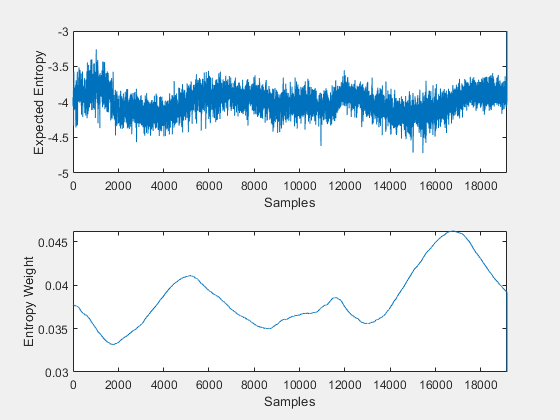

Episode: 193/400 | Episode reward:    31.09 | Episode steps:  100 | Average reward:    29.83 | Step Count: 19250 | Episode Q0:    -1.04


if doTraining
    save_system(mdl)
    trainingStats = train(agent,env,trainOpts);
    
    % !!! RUN the following lines to save current agent and workspace!
    currentTimestr = datestr(now,'yyyy_mmmm_dd_HH_MM');
    save(append(SaveAgentDir,'\agent_', currentTimestr,'.mat'),'agent','trainingStats');
    save(append(SaveAgentDir,'\workspace_seedNum',num2str(seedNum),'_', currentTimestr,'.mat'));
    %---------------------%
else
    rotVariance = 0;
    fnVariance = 0;
    speedVariance = 0;
    agent.AgentOptions.UseDeterministicExploitation = 1;

%     randObs = {rand(obsInfo(1).Dimension)};
%     DistributionParams = evaluate(agent.Actor, randObs);
%     DistributionParams = DistributionParams{1};
% 
%     figure('Name','Current agent info. with a randObs','NumberTitle','off')
%     set(gcf,'Visible','on')
%     subplot(3,1,1)
%     plot(DistributionParams(1:4),'LineWidth',2)
%     xticks(1:1:4)
%     xlabel('Action number')
%     ylabel('Action distribution mean')
%     hold off
%     
    subplot(3,1,2)
    plot(DistributionParams(5:8),'LineWidth',2)
    xticks(1:1:4)
    xlabel('Action number')
    ylabel('Action distribution std')
    hold off

    subplot(3,1,3)
    for i = 1:1:50
        actionOut = getAction(agent,randObs);
        plot(actionOut{1},'LineWidth',1)
        hold on
    end
    xticks(1:1:4)
    xlabel('Action number')
    ylabel('Action for a randObs')
    hold off

    tic
    simout = sim('RLvali_2021b.slx');
    toc

    figure('Name','Robot body information','NumberTitle','off')
    set(gcf,'Visible','on')
    subplot(4,1,1)
    plot(simout.COT.Time, simout.COT.Data,'LineWidth',2)
    xlabel('Time (s)')
    ylabel('Reward')
    hold off
    
    subplot(4,1,2)
    hold on
    plot(simout.FLfootTrace.Time, simout.FLfootTrace.Data(:,1),'LineWidth',2)
    plot(simout.FLfootTrace.Time, simout.FLfootTrace.Data(:,2),'LineWidth',2)
    plot(simout.FLfootTrace.Time, simout.FLfootTrace.Data(:,3),'LineWidth',2)
    legend('x','y','z')
    xlabel('Time (s)')
    ylabel('position (m)')
    hold off
    
    subplot(4,1,3)
    hold on
    plot(simout.Observations.vx.Time, simout.Observations.vx.Data,'LineWidth',2)
    plot(simout.Observations.vy.Time, simout.Observations.vy.Data,'LineWidth',2)
    plot(simout.Observations.vz.Time, simout.Observations.vz.Data,'LineWidth',2)
    legend('vx','vy','vz')
    xlabel('Time (s)')
    ylabel('Speed (m/s)')
    hold off
    
    subplot(4,1,4)
    
    rotData = reshape(simout.Observations.rot.Data,size(simout.Observations.rot.Data,[1,3]));
    hold on
    plot(simout.Observations.rot.Time, rotData(1,:),'LineWidth',2)
    plot(simout.Observations.rot.Time, rotData(2,:),'LineWidth',2)
    plot(simout.Observations.rot.Time, rotData(3,:),'LineWidth',2)
    legend('rotX','rotY','rotZ')
    xlabel('Time (s)')
    ylabel('Rotate (rad)')
    hold off
    
    figure('Name','Robot leg information','NumberTitle','off')

    windowSize = 1; 
    b = (1/windowSize)*ones(1,windowSize);
    a = 1;

    set(gcf,'Visible','on')
    subplot(4,1,1)
    hold on
    plot(simout.Observations.SigsFromLegs.FnFR.Time,simout.Observations.SigsFromLegs.FnFR.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnFL.Time,simout.Observations.SigsFromLegs.FnFL.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnRR.Time,simout.Observations.SigsFromLegs.FnRR.Data,'LineWidth',2)
    plot(simout.Observations.SigsFromLegs.FnRL.Time,simout.Observations.SigsFromLegs.FnRL.Data,'LineWidth',2)
    legend('FnFR','FnFL','FnRR','FnRL')
    xlabel('Time (s)')
    ylabel('Contact force (N)')
    hold off
    
    subplot(4,1,2)
    hold on
    bendFRData = reshape(simout.Observations.SigsFromLegs.bendFR.Data,size(simout.Observations.SigsFromLegs.bendFR.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendFR.Time,filter(b,a,bendFRData(2,:)),'LineWidth',2)
    bendFLData = reshape(simout.Observations.SigsFromLegs.bendFL.Data,size(simout.Observations.SigsFromLegs.bendFL.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendFL.Time,filter(b,a,bendFLData(2,:)),'LineWidth',2)
    bendRRData = reshape(simout.Observations.SigsFromLegs.bendRR.Data,size(simout.Observations.SigsFromLegs.bendRR.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendRR.Time,filter(b,a,bendRRData(2,:)),'LineWidth',2)
    bendRLData = reshape(simout.Observations.SigsFromLegs.bendRL.Data,size(simout.Observations.SigsFromLegs.bendRL.Data,[1,3]));
    plot(simout.Observations.SigsFromLegs.bendRL.Time,filter(b,a,bendRLData(2,:)),'LineWidth',2)
    legend('bendFR','bendFL','bendRR','bendRL')
    xlabel('Time (s)')
    ylabel('Bending angle (rad)')
    hold off
    
    subplot(4,2,5)
    hold on
    plotStartStep = 1; %find(simout.FLfootTrace.Time > (startAgentTime-0.9), 1);
    plotEndStep = size(simout.FLfootTrace.Time,1); % find(simout.FLfootTrace.Time > (startAgentTime-0.1), 1);
    plot(simout.FLfootTrace.Data(plotStartStep:plotEndStep,1),simout.FLfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('FL foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,6)
    hold on
    plot(simout.FRfootTrace.Data(plotStartStep:plotEndStep,1),simout.FRfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('FR foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,7)
    hold on
    plot(simout.RLfootTrace.Data(plotStartStep:plotEndStep,1),simout.RLfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('RL foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

    subplot(4,2,8)
    hold on
    plot(simout.RRfootTrace.Data(plotStartStep:plotEndStep,1),simout.RRfootTrace.Data(plotStartStep:plotEndStep,3),'LineWidth',2)
    legend('RR foot trace')
    xlabel('x (m)')
    ylabel('z (m)')
    hold off

end